T=readtable('C:\Users\Corentin\OneDrive\Bureau\ECL 1\S5\MTH\Statistiques\taille.txt',ReadVariableNames=true);

ligne_h=T.sexe==1;
TH=T(ligne_h,:);
plot(TH.t_pere,TH.taille,'.')
hold on
p=polyfit(TH.t_pere,TH.taille,1)

p =     0.5139    0.8908


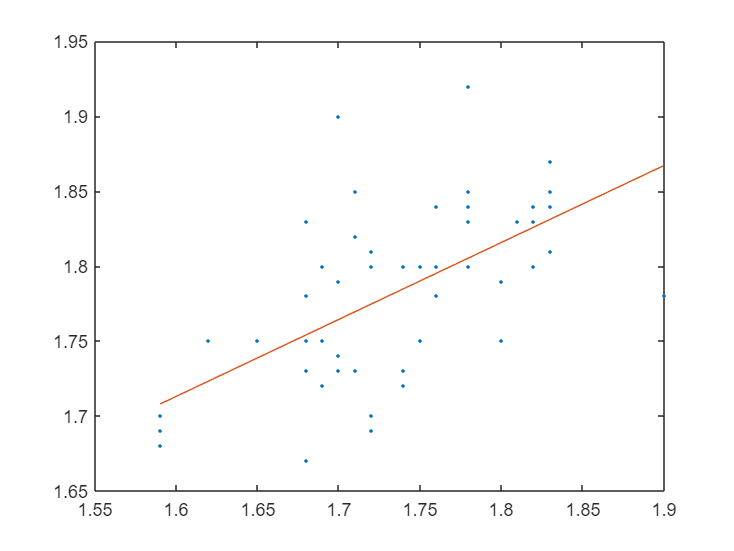

plot(TH.t_pere,polyval(p,TH.t_pere))

model='taille~t_pere';
LM=fitlm(TH,model)

LM = Linear regression model:
    taille ~ 1 + t_pere

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)    0.89084     0.17809    5.0023    7.6758e-06
    t_pere         0.51386     0.10253     5.012    7.4234e-06


Number of observations: 51, Error degrees of freedom: 49
Root Mean Squared Error: 0.0491
R-squared: 0.339,  Adjusted R-Squared: 0.325
F-statistic vs. constant model: 25.1, p-value = 7.42e-06